# Measuring the site mixing zone

This guide explains how to measure a mixing zone around a given site's cage layout.

## About

A mixing zone is an area defined by a regulatory standard and which delimts the zone in whcih certain environmental conditions can be breached. SEPA employs a 100 m mixing zone for the regulation of certain discharges associated with aquaculture sites. This areais calculated by considered the area which is within 100 m from the perimeter of the farm cages.

## Calculate 100 m mixing zone area

Assuming we have cage information initialised in Matlab, it is trivial to calculate the 100 m mixing zone.

run  = project.solidsRuns.first;
site = run.cages;

site.compositeArea

ans =           109107.190649491

By default, this method returns the area within 100 m of the farm cages - taken relative to the cage perimeters. The term "composite" is used because this calculation is based on 100 m mixing zones being applied to all cages individually and then combined, with any overlapping areas reconciled.

In this case, the 100 m mixing zone is ~109,000 m2.

## Calculate a different mixing area

Additional arguments can be passed to the .compositeArea() method in order to change the behavior.

To use a distance other than (the default) 100 m:

site.compositeArea('radialDistance', 50)

ans =            54696.359112313

which gives the area based on a 50 m mixing zone distance.

Or if the distance is to be calculated from the cage centre rather than (the default) cage perimeter:

site.compositeArea('cageEdge', 0)

ans =           90187.6402998343

Note that this latter value is smaller than the original (100 m) area of ~109,000 m2 as it does not include the width of the cages in the calculation.

These two arguments can be use together.

## Plotting the notional mixing zone

Next, we can simply make a plot of the notional perimeter associated with the mixing zone.

run.plot('impact', 0)

ans =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [0 0 600 600]
       Units: 'points'

  Show all properties

[x,y] = site.cagePerimeter
hold on

x =           350420.278677024          350427.528628435          350434.721241987           350441.82813172          350448.821249988          350455.672998147          350462.356335478          350468.844885902          350475.113042074          350481.136066446          350486.890188892          350492.352700519          350497.502043291          350502.317895103          350506.781249988          350510.874493124          350514.581470351          350517.887551922          350520.779690244          350523.246471369          350525.278160038          350526.533384205          350527.118082142          350531.211325278          350534.918302505          350538.224384076          350541.116522398          350543.583303523          350545.614992192          350547.203570259           350548.34276833          350549.028090513          350549.256832154          350549.028090513           350548.34276833          350547.203570259          350545.614992192          350543.583303523        

y =           1069241.69125836          1069241.00593618           1069239.8667381          1069238.27816004          1069236.24647137          1069233.77969024          1069230.88755192          1069227.58147035          1069223.87449312          1069219.78124999           1069215.3178951          1069210.50204329          1069205.35270052          1069199.89018889          1069194.13606645          1069188.11304207           1069181.8448859          1069175.35633548          1069168.67299815          1069161.82124999          1069154.82813172           1069149.2125816          1069148.45879357          1069142.43576919          1069136.16761302           1069129.6790626          1069122.99572527          1069116.14397711          1069109.15085884          1069102.04396911          1069094.85135555          1069087.60140414          1069080.32272712           1069073.0440501          1069065.79409869          1069058.60148513           1069051.4945954          1069044.50147713        

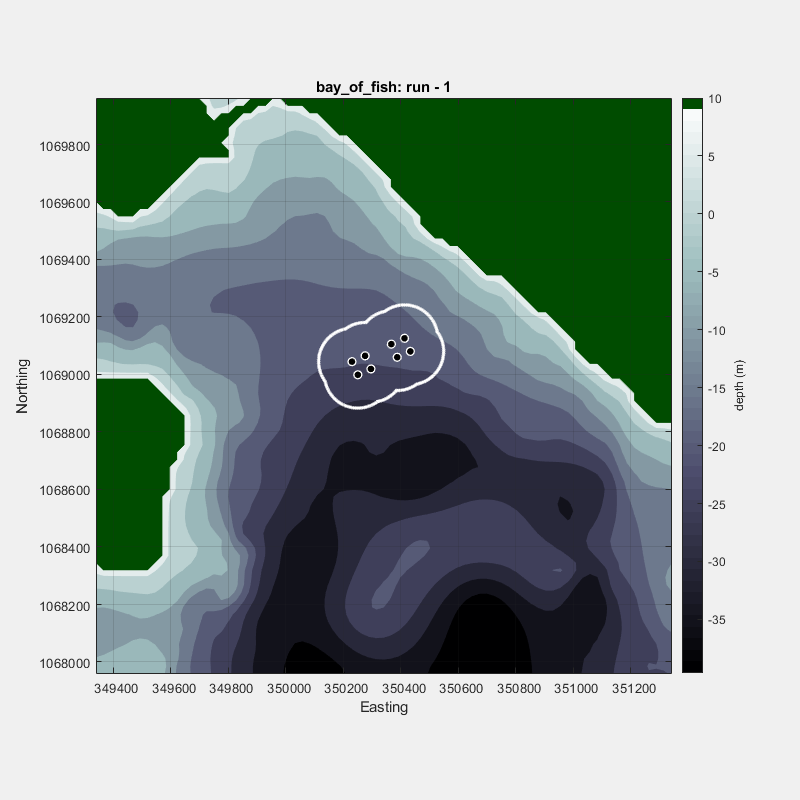

scatter3(x,y, repmat(15, numel(x),1),  'w.')

Notice that, at least according to SEPA regulatory approaches, this line is *notional*. It does not represent a limit on environmental impacts in absolute space. It defines an *equivalent area* which represents the maximum scale of some types of impact.

Notice also the use of the `.cagePerimeter()` method. This returns the coordinates of the perimeter around the farm. By default it returns a composite perimeter which is 100 m from the cage perimeters. A different distance can be specified using the `'radialDistance'` argument.